# SISTEMAS DE CONTROL II

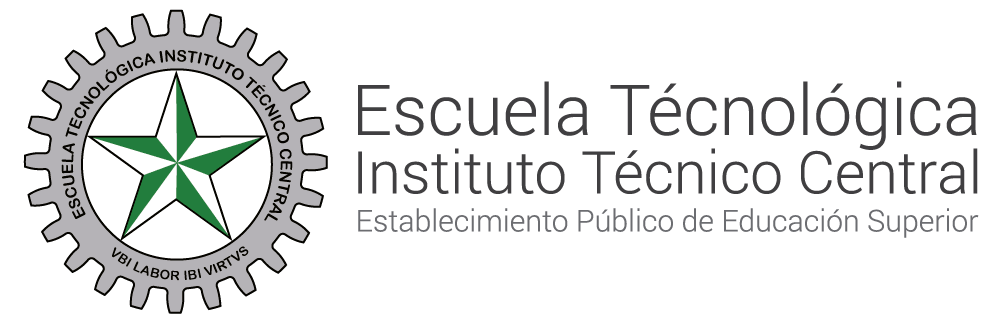

# TRASFORMADA Z

**Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c**

encuentre la transformada z de :


$$y\left\lbrack k\right\rbrack =\mathrm{kT}e^{-\mathrm{aTk}}$$


para esto vamos a recordar la definicion de com transformar una funcion Y(k) a ternimos de z para la cual aplicamos la siguiente definicon 

    
$$Z\left\lbrace y\left\lbrack k\right\rbrack \right\rbrace =Y\left(z\right)=\sum_{k=0\;}^{k=\infty } y\left\lbrack k\right\rbrack z^{-k}$$



$$Y\left(z\right)=\sum_{k=0\;}^{k=\infty } k{\mathrm{Te}}^{-\mathrm{akT}} z^{-k}$$


Partiendo de 


$$\sum_{k=0\;}^{k=\infty } e^{-\mathrm{akT}} z^{-k} =\frac{z}{z-e^{-\mathrm{aT}} }$$


Derivamos a ambos lados de la igualdad con respecto a  con respecto a Z


$$\frac{\mathrm{d}}{\mathrm{dk}}\left(\sum_{k=0\;}^{k=\infty } e^{-\mathrm{akT}} z^{-k} \right)=\frac{d}{\mathrm{dz}}\left(\frac{z}{z-e^{-\mathrm{aT}} }\right)$$


Resolviendo primero la parte izquierda de la igualda obtendriamos el siguiente desarrollo:


$$\frac{\mathrm{d}}{\mathrm{dz}}\left(\sum_{k=0\;}^{k=\infty } e^{-\mathrm{akT}} z^{-k} \right)$$


syms f(k) a T z
A=(exp(-a*T)*z^(-1))^(k);


$$\frac{\mathrm{d}}{\mathrm{dz}}\left(\sum_{k=0\;}^{k=\infty } e^{-\mathrm{akT}} z^{-k} \right)={-k*e}^{-\mathrm{akT}} z^{-k-1} ={-k*e}^{-\mathrm{akT}} z^{-k} z^{-1}$$


simplify(diff(A))

$$ans = -\frac{k\,{\left(\frac{{\mathrm{e}}^{-T\,a}}{z}\right)}^{k}}{z}$$

Ahora se resuelve la derivada con respecto a z de la parte derecha de la igualdad:


$$\frac{d}{\mathrm{dz}}\left(\frac{z}{z-e^{-\mathrm{aT}} }\right)=\frac{z-e^{-\mathrm{aT}} -z}{{\left(z-e^{-\mathrm{aT}} \right)}^2 }$$



$$\frac{d}{\mathrm{dz}}\left(\frac{z}{z-e^{-\mathrm{aT}} }\right)=\frac{z-e^{-\mathrm{aT}} -z}{{\left(z-e^{-\mathrm{aT}} \right)}^2 }=\frac{-e^{-\mathrm{aT}} }{{\left(z-e^{-\mathrm{aT}} \right)}^2 }$$


A=exp(-a*T*k);
f(k) = A;
F = ztrans(f);
simplify(diff(F))

$$ans = -\frac{{\mathrm{e}}^{T\,a}}{{\left(z\,{\mathrm{e}}^{T\,a}-1\right)}^{2}}$$

ahora igualamos 


$$\sum_{k=0\;}^{k=\infty } {-k*e}^{-\mathrm{akT}} z^{-k} z^{-1} =\frac{-e^{-\mathrm{aT}} }{{\left(z-e^{-\mathrm{aT}} \right)}^2 }$$


 multiplicando ambos lados de la igualdad por z, -1 y por T obtenemos la solución:


$$\sum_{k=0\;}^{k=\infty } {\mathrm{kT}*e}^{-\mathrm{akT}} z^{-k} =\frac{\mathrm{zT}e^{-\mathrm{aT}} }{{\left(z-e^{-\mathrm{aT}} \right)}^2 }$$


syms f(k) a T z
A=exp(-a*T*k);
B=k*T;
F=ztrans(A*B)

$$F = \frac{T\,z\,{\mathrm{e}}^{T\,a}}{{\left(z\,{\mathrm{e}}^{T\,a}-1\right)}^{2}}$$